********************
* SensorDataReader started on 192.168.31.5:3400
********************
Connection accepted from 192.168.31.116:42284


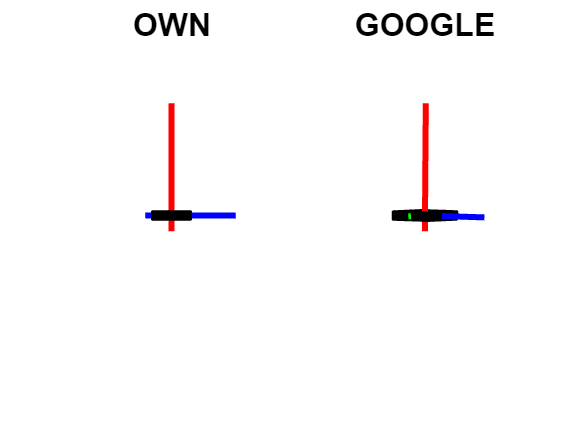

[xhat, meas] = filterTemplate();

# Task2

%filter and away from disturbance

[mu_acc, Sigma_acc] = approxGaussianTransform(meas.acc(:, ~any(isnan(meas.acc), 1)))

mu_acc =    -0.1686
    0.0941
    9.8678


Sigma_acc =     0.0015   -0.0007    0.0000
   -0.0007    0.0017   -0.0002
    0.0000   -0.0002    0.0006


[mu_gyr, Sigma_gyr] = approxGaussianTransform(meas.gyr(:, ~any(isnan(meas.gyr), 1)))

mu_gyr = 1.0e-03 *

    0.1645
    0.2046
   -0.2818


Sigma_gyr = 1.0e-05 *

    0.1362    0.0703   -0.0174
    0.0703    0.1070   -0.0310
   -0.0174   -0.0310    0.1698


[mu_mag, Sigma_mag] = approxGaussianTransform(meas.mag(:, ~any(isnan(meas.mag), 1)))

mu_mag =    -6.2878
   16.6904
  -29.4290


Sigma_mag =     0.1018    0.0007   -0.0283
    0.0007    0.1135   -0.0079
   -0.0283   -0.0079    0.1100


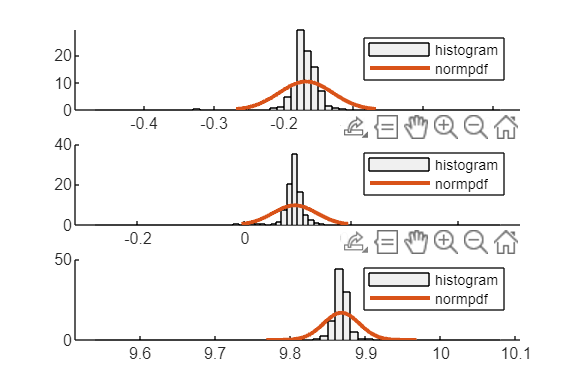

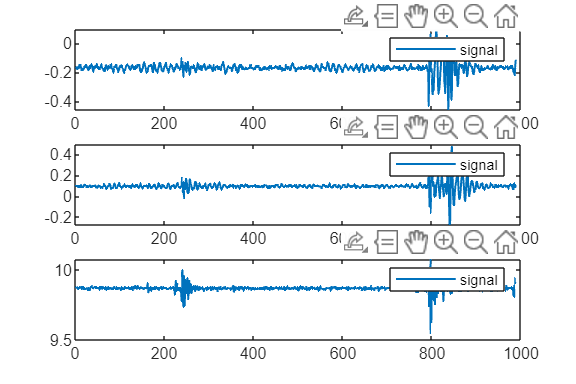

t1=meas.acc(:, ~any(isnan(meas.acc),1));
t2=meas.gyr(:, ~any(isnan(meas.gyr),1));
t3=meas.mag(:, ~any(isnan(meas.mag),1));
plothistogram(t1,mu_acc,Sigma_acc,0.1,t1);

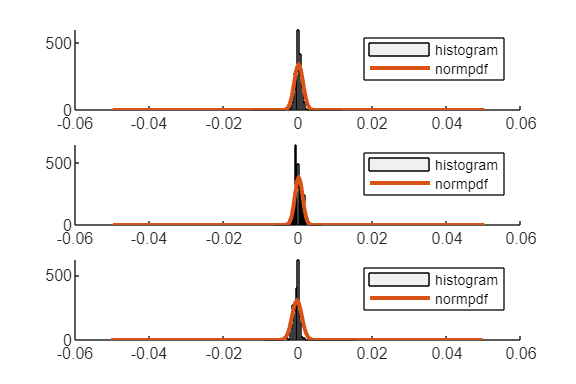

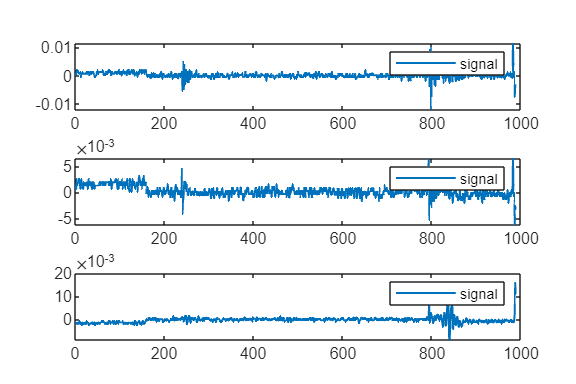

plothistogram(t2,mu_gyr,Sigma_gyr,0.05,t2);

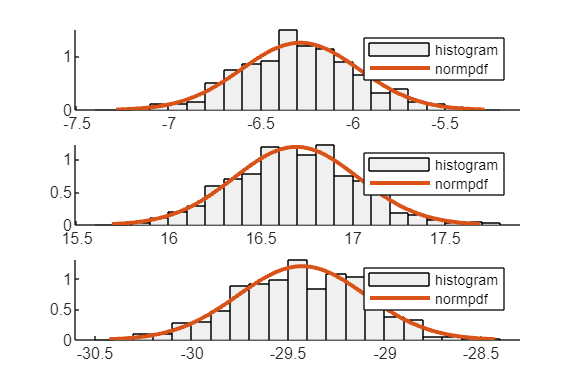

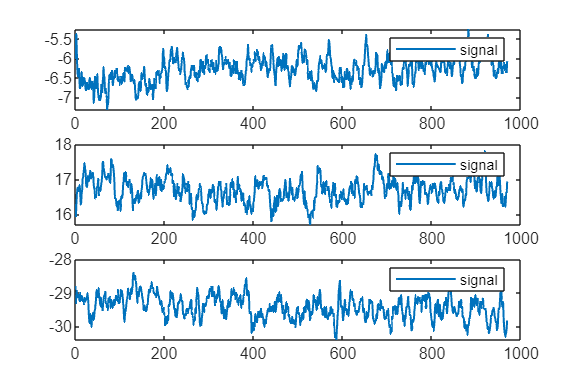

plothistogram(t3,mu_mag,Sigma_mag,1,t3);

# Task 3

%see note

# Task 4